std_id = 330724

std_id = 330724

rng(std_id); 
N=20;
A=[randn(N/2,1) rand(N/2,1)+0.5;randn(N/2,1) -rand(N/2,1)-0.5]

A =     0.4295    0.6356
   -2.1590    0.9033
    0.5304    0.7784
   -0.6501    0.6757
    1.3073    0.8734
    0.2607    1.0577
   -0.0841    0.8834
    0.7465    0.6707
   -0.4278    1.1648
   -0.0607    1.4810


angle=randn(1);
x(:,1)=A(:,1)*cos(angle)-A(:,2)*sin(angle);
x(:,2)=A(:,1)*sin(angle)+A(:,2)*cos(angle);
x=x+randn(1,2)

x =    -0.0326    2.0515
   -2.3703    0.9084
   -0.0226    2.2261
   -0.9697    1.5141
    0.5863    2.7179
   -0.3992    2.3203
   -0.5995    1.9898
    0.2178    2.2491
   -1.0400    2.0466
   -0.8960    2.5093


y=[-ones(N/2, 1); ones(N/2, 1)]

y =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


% Define the necessary variables for creating_learning_animation
point_signs = ['o', 'x']; 
plot_title = 'Perceptron Learning Animation '; 
axis_vec = [-3, 3, -3, 3]; 
path = './gif/'; 

% CASE1.1: LEARNING RATE=0.01
w=[1 1]

w =      1     1


rate=0.01

rate = 0.0100

ans = "Iter 1"

ans = "12 errors - error rate : 60.000000"

ans = "w=[1.018055 0.793655], b=0.386545"

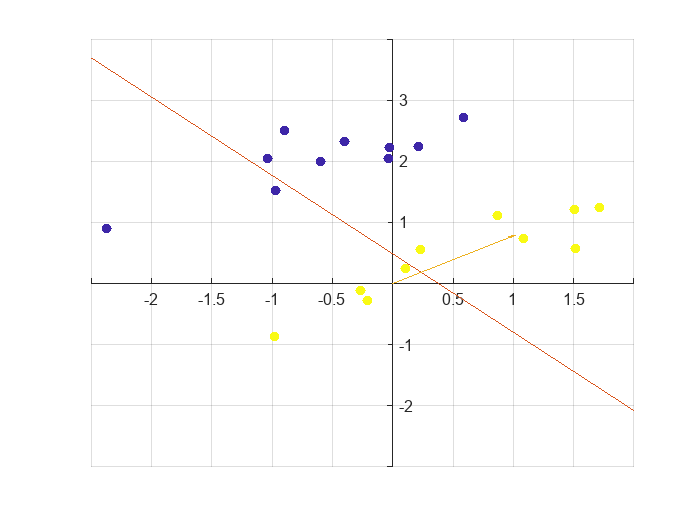

ans = "Iter 2"

ans = "11 errors - error rate : 55.000000"

ans = "w=[1.007053 0.648010], b=0.541162"

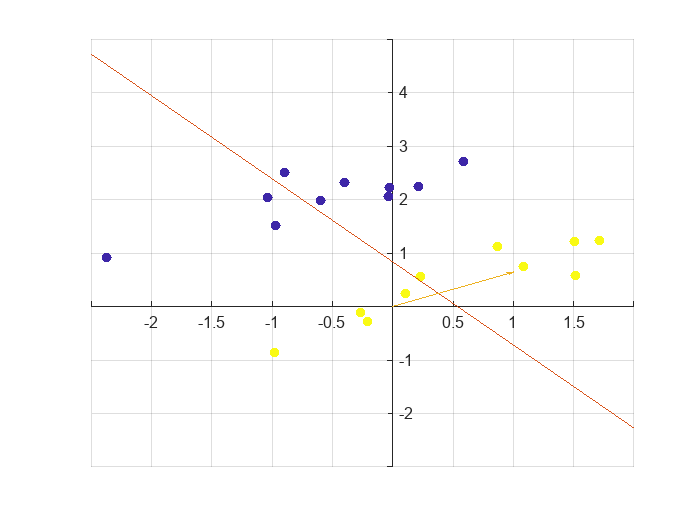

ans = "Iter 3"

ans = "10 errors - error rate : 50.000000"

ans = "w=[0.992375 0.527900], b=0.541162"

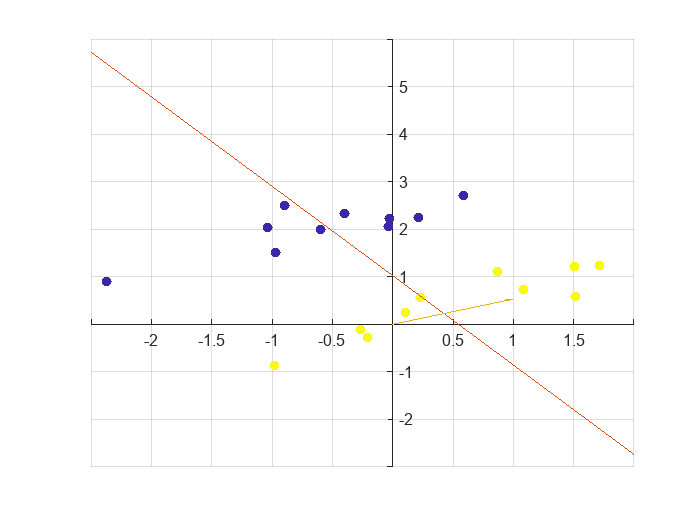

ans = "Iter 4"

ans = "9 errors - error rate : 45.000000"

ans = "w=[0.973705 0.430992], b=0.463853"

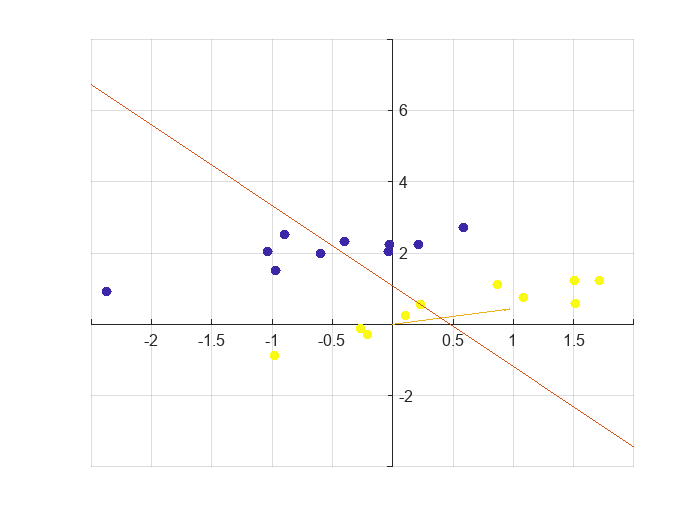

ans = "Iter 5"

ans = "9 errors - error rate : 45.000000"

ans = "w=[0.955035 0.334085], b=0.386545"

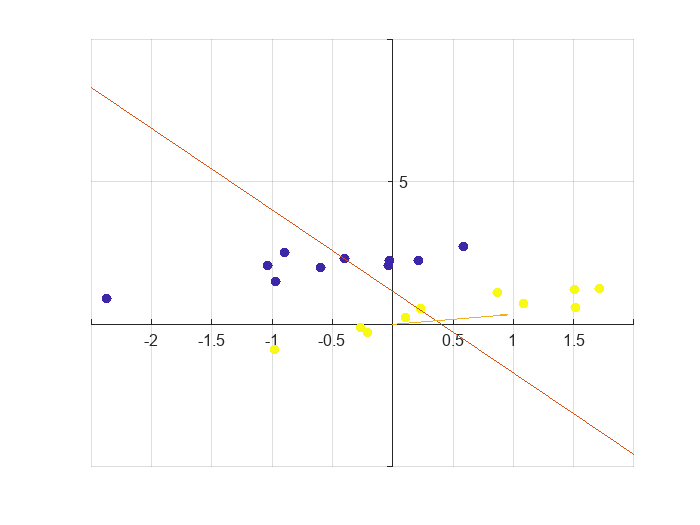

ans = "Iter 6"

ans = "8 errors - error rate : 40.000000"

ans = "w=[0.936365 0.237177], b=0.309236"

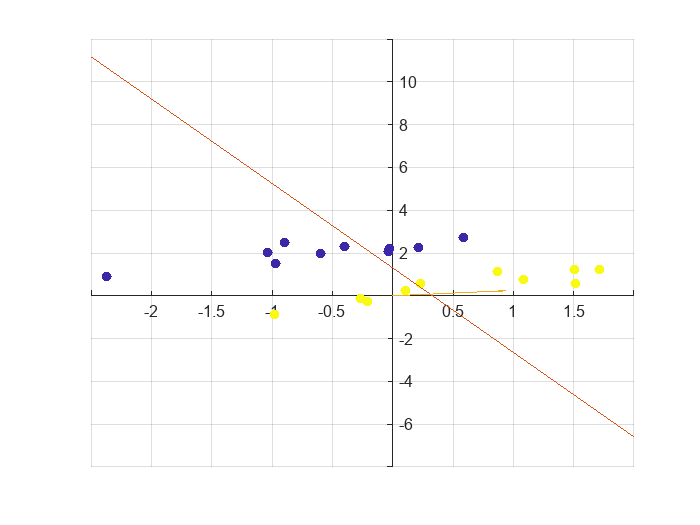

ans = "Iter 7"

ans = "8 errors - error rate : 40.000000"

ans = "w=[0.917695 0.140270], b=0.231927"

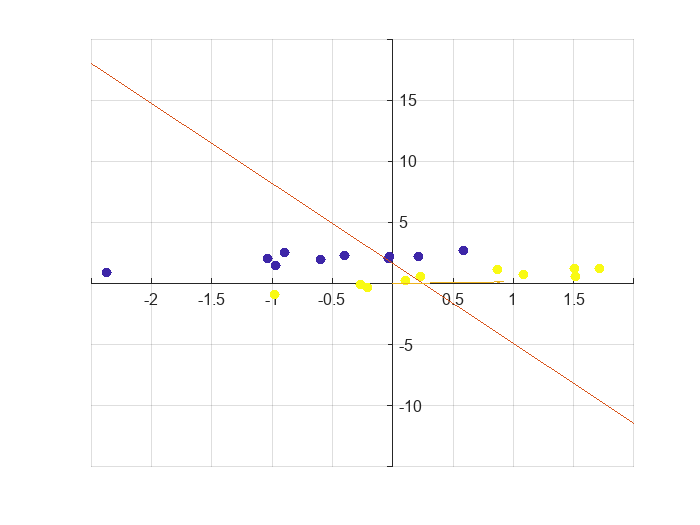

ans = "Iter 8"

ans = "6 errors - error rate : 30.000000"

ans = "w=[0.896480 0.059986], b=0.154618"

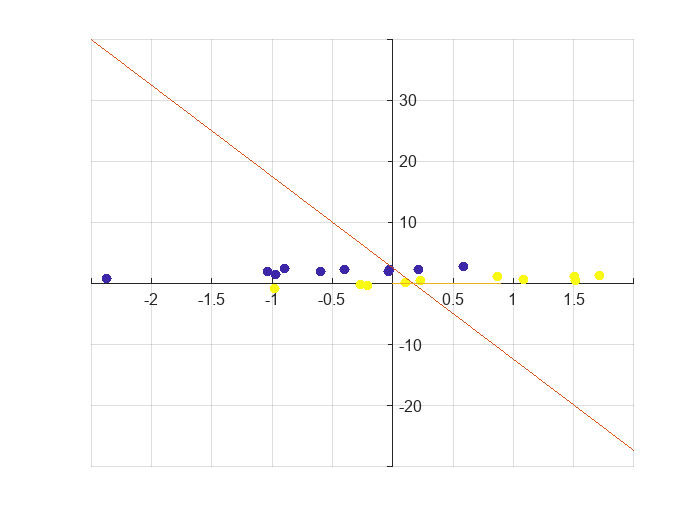

ans = "Iter 9"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.874938 0.000218], b=-0.000000"

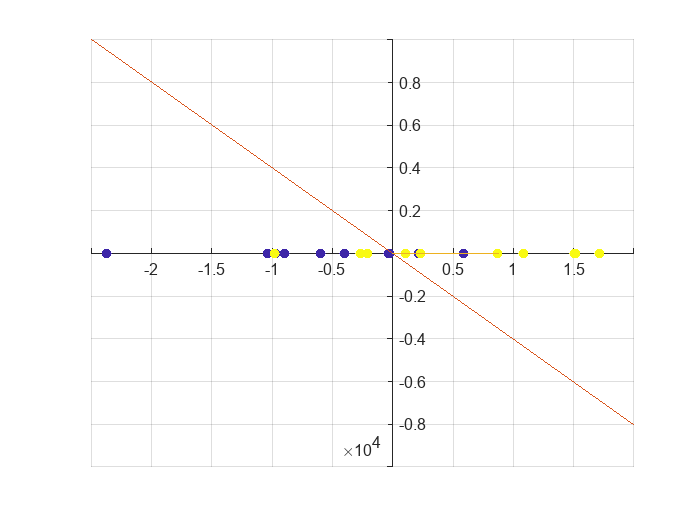

ans = "Iter 10"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.852309 -0.062024], b=-0.077309"

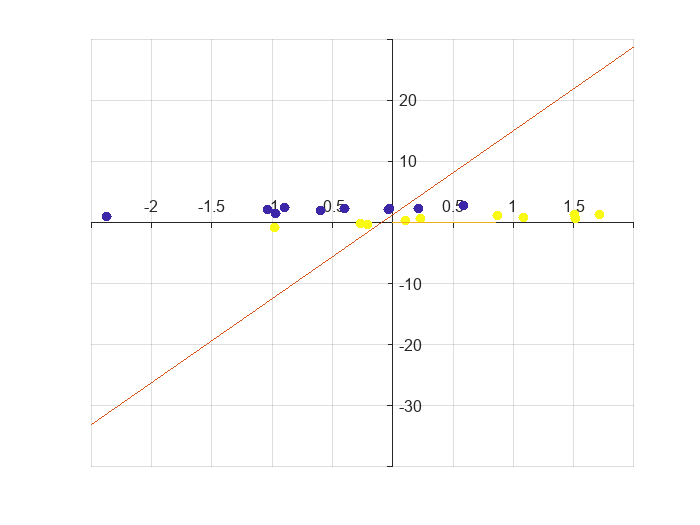

ans = "Iter 11"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.831858 -0.101774], b=-0.231927"

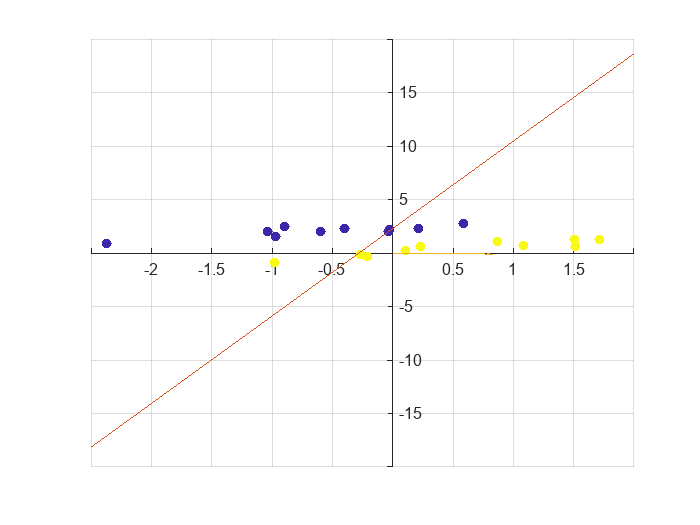

ans = "Iter 12"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.811344 -0.161185], b=-0.231927"

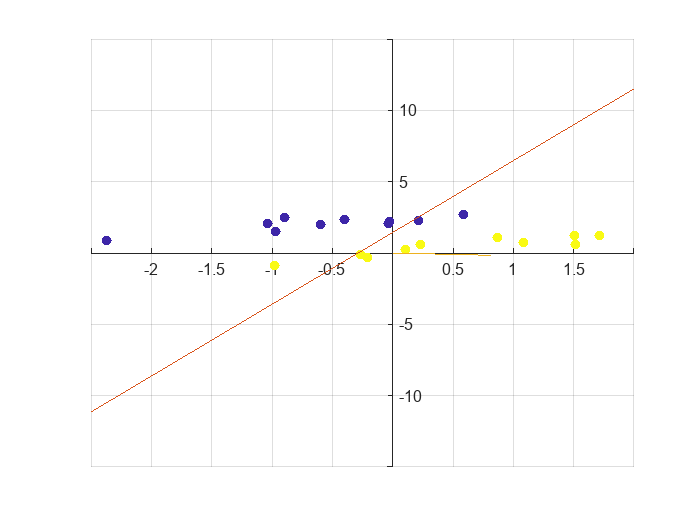

ans = "Iter 13"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.795654 -0.197014], b=-0.231927"

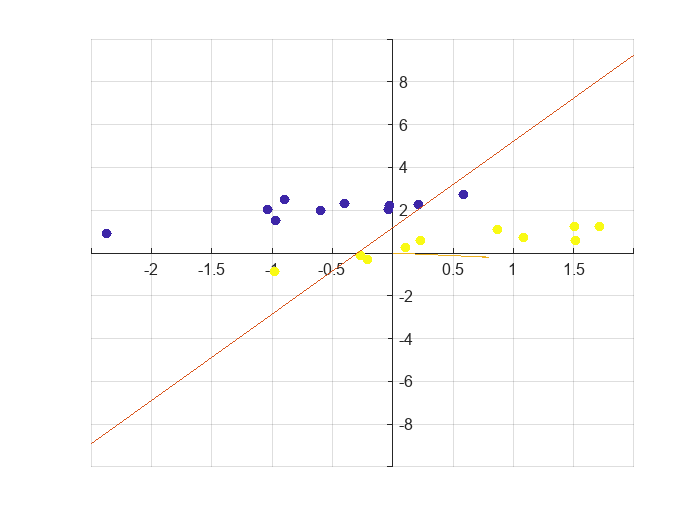

ans = "Iter 14"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.779964 -0.232843], b=-0.231927"

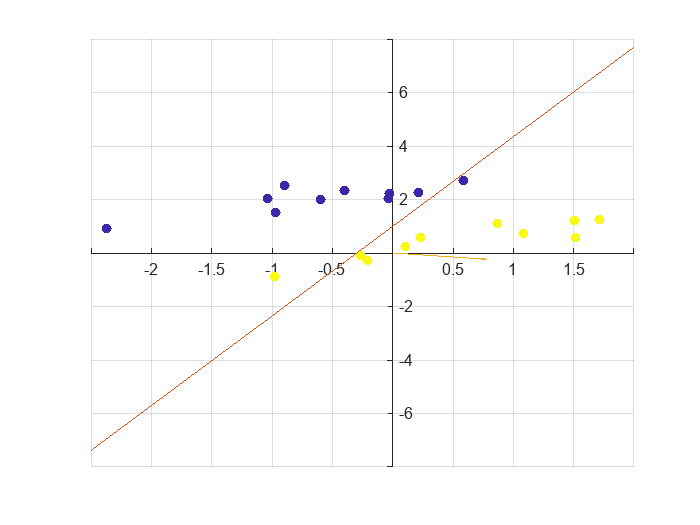

ans = "Iter 15"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.764274 -0.268672], b=-0.231927"

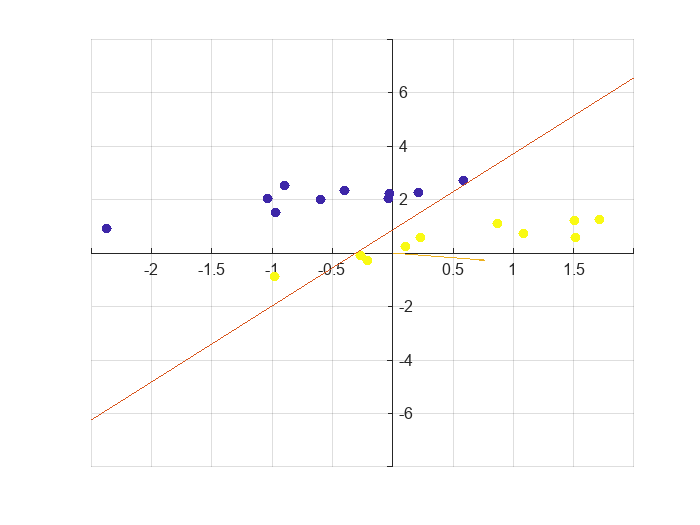

ans = "Iter 16"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.754447 -0.277322], b=-0.309236"

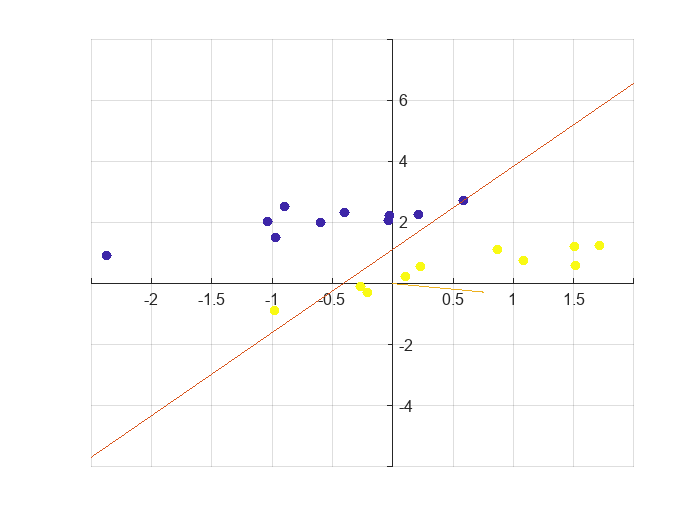

ans = "Iter 17"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.744619 -0.285971], b=-0.386545"

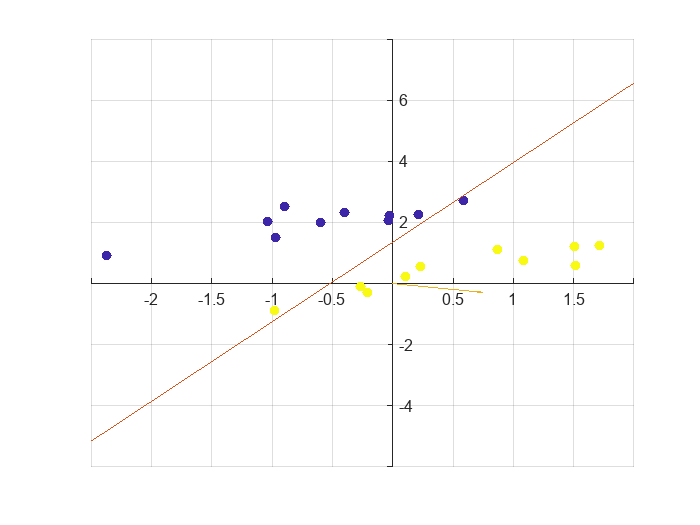

ans = "Iter 18"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.728929 -0.321800], b=-0.386545"

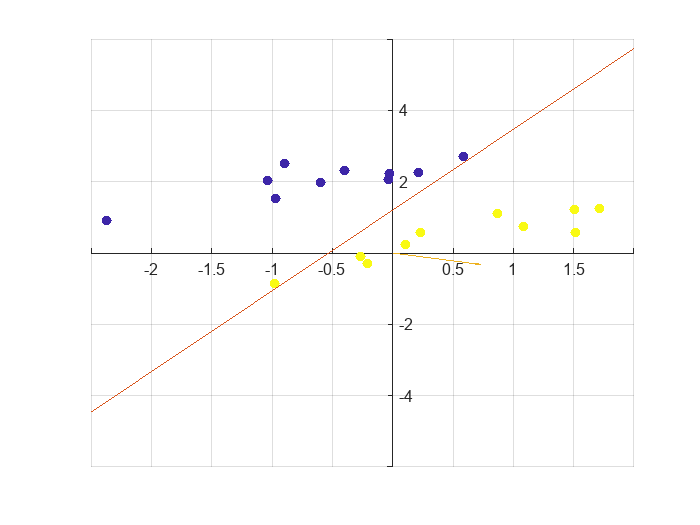

ans = "Iter 19"

ans = "0 errors - error rate : 0.000000"

ans = "w=[0.719102 -0.330450], b=-0.463853"

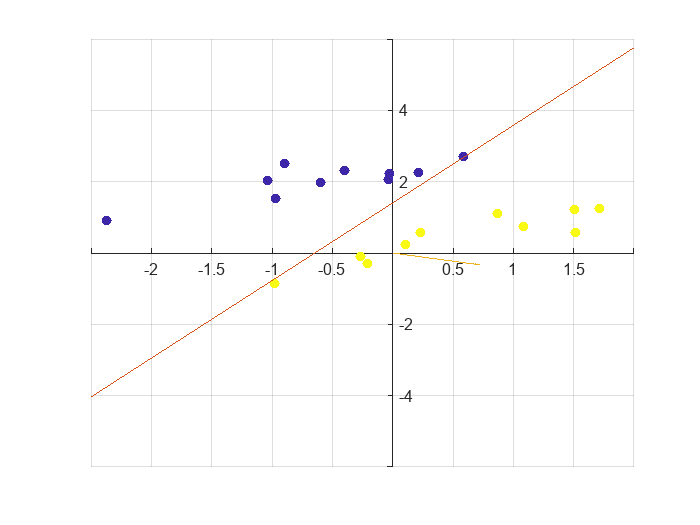

filename = 'animation_case1_1.gif';
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

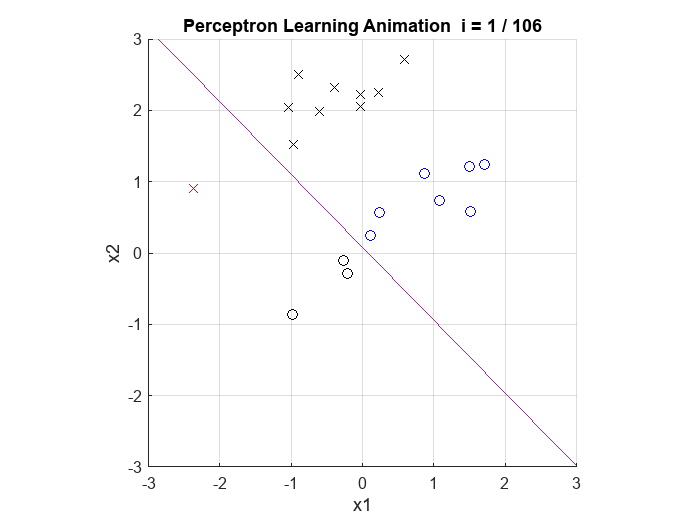

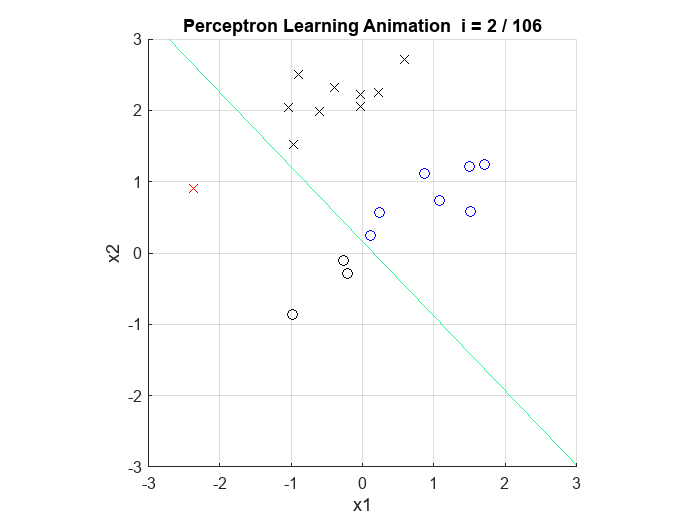

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);

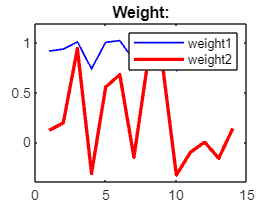

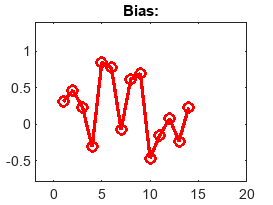

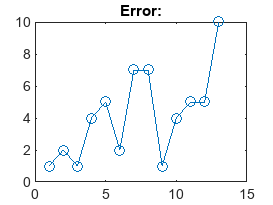

percept_plot(w1,b1,erc1);

% CASE1.2: LEARNING RATE=0.5
w=[1 1]

w =      1     1


rate=0.5

rate = 0.5000

ans = "Iter 1"

ans = "10 errors - error rate : 50.000000"

ans = "w=[0.579288 -0.334594], b=-3.865445"

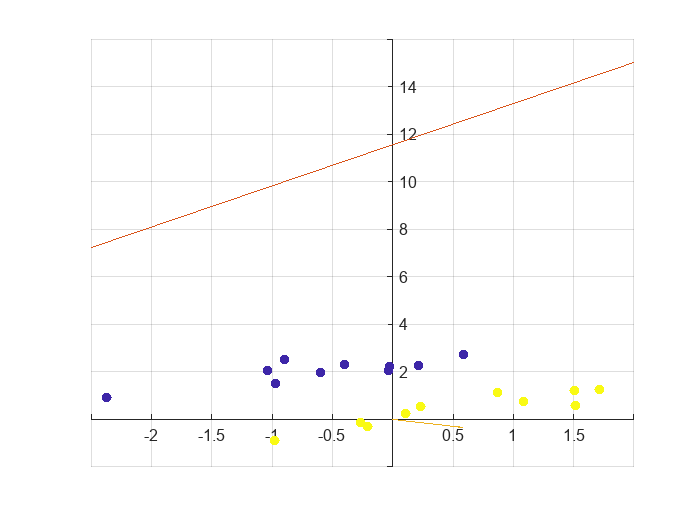

ans = "Iter 2"

ans = "9 errors - error rate : 45.000000"

ans = "w=[1.453643 -0.738901], b=-3.865445"

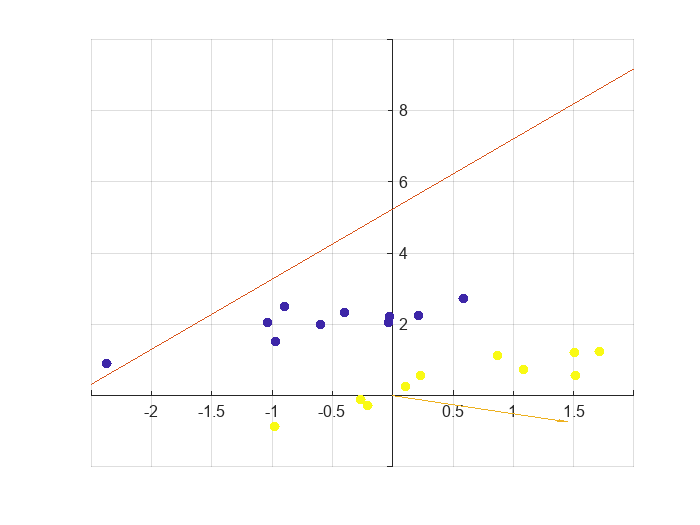

ans = "Iter 3"

ans = "4 errors - error rate : 20.000000"

ans = "w=[1.524297 -1.641014], b=-3.865445"

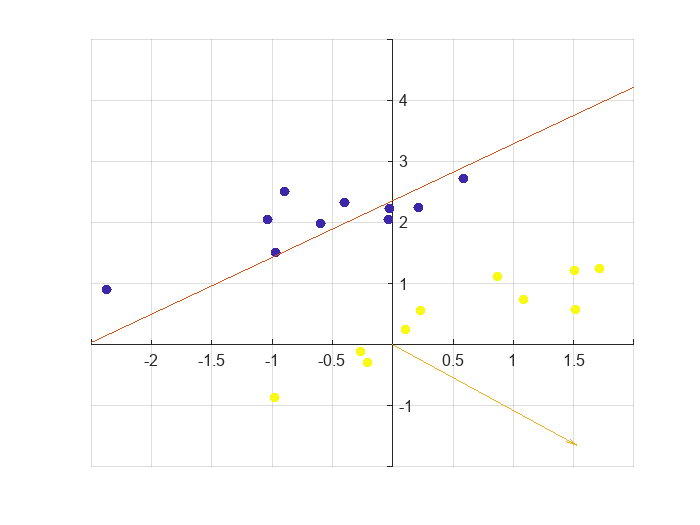

ans = "Iter 4"

ans = "0 errors - error rate : 0.000000"

ans = "w=[2.398651 -2.045321], b=-3.865445"

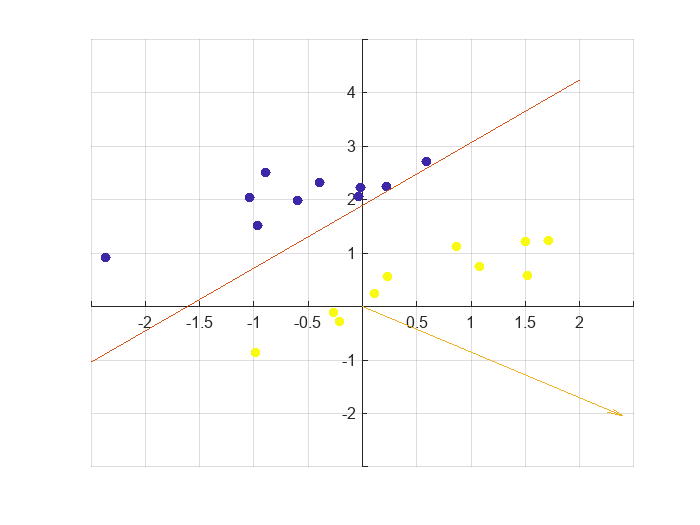

filename = 'animation_case1_2.gif'; % Define the filename for this case
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

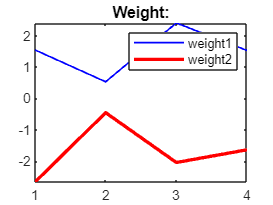

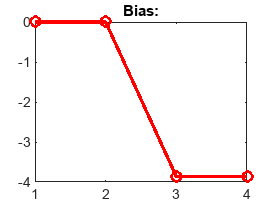

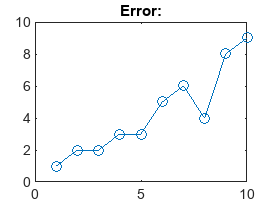

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

% CASE1.3: LEARNING RATE=0.75
w=[1 1]

w =      1     1


rate=0.75

rate = 0.7500

ans = "Iter 1"

ans = "10 errors - error rate : 50.000000"

ans = "w=[1.574483 -0.255183], b=-5.798168"

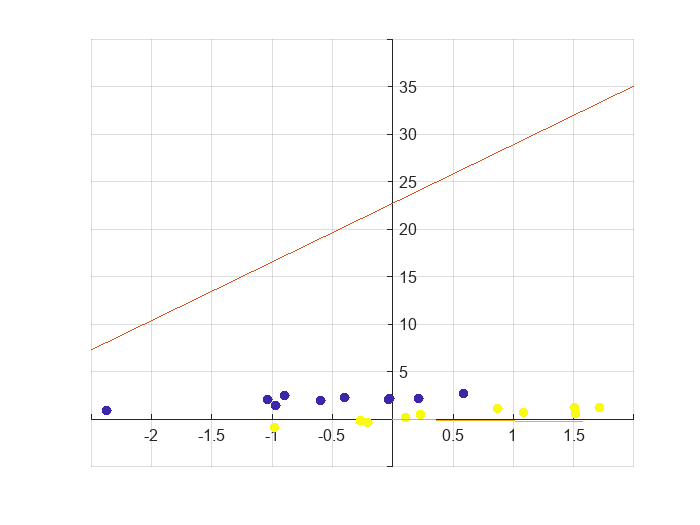

ans = "Iter 2"

ans = "6 errors - error rate : 30.000000"

ans = "w=[0.861906 -2.442564], b=-5.798168"

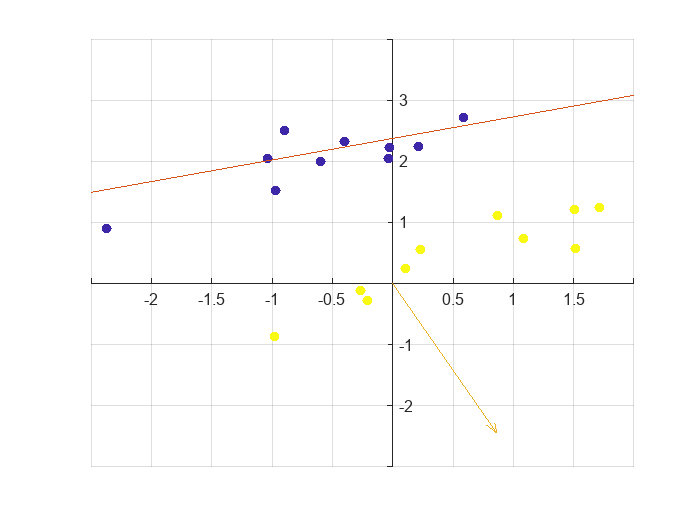

ans = "Iter 3"

ans = "0 errors - error rate : 0.000000"

ans = "w=[2.173437 -3.049025], b=-5.798168"

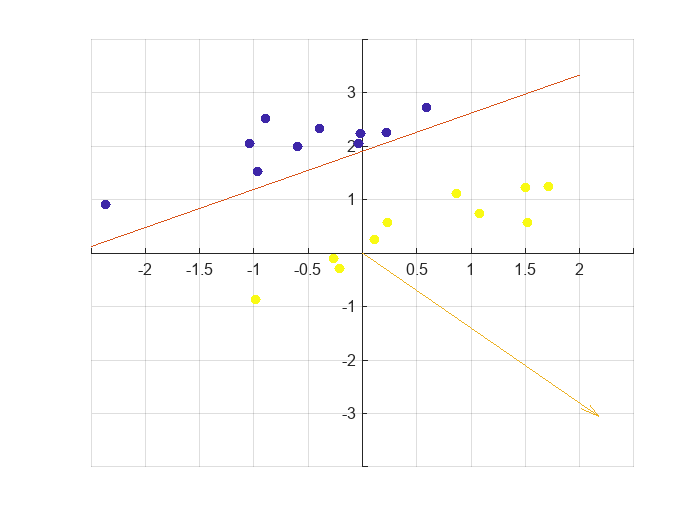

filename = 'animation_case1_3.gif'; % Define the filename for this case
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

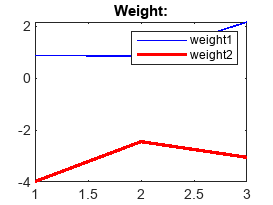

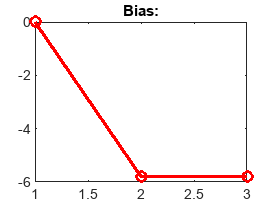

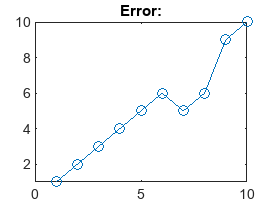

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

% initial classifier 1 : LEARNING RATE=0.01,w=[1 0]
w=[1 0]

w =      1     0


rate=0.01

rate = 0.0100

ans = "Iter 1"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.977371 -0.062242], b=-0.077309"

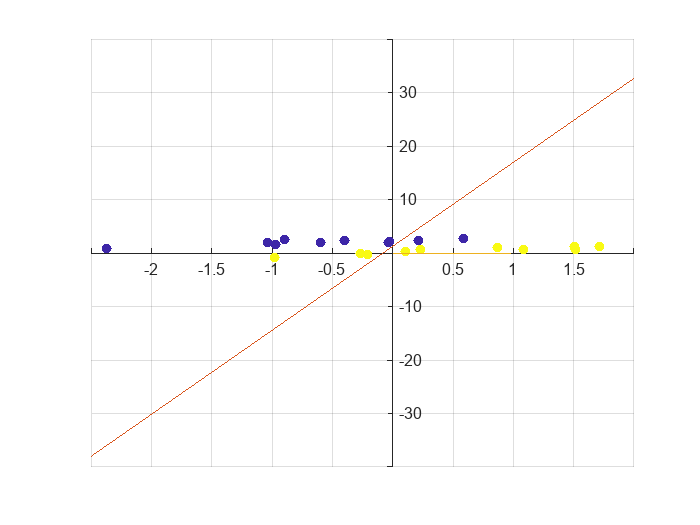

ans = "Iter 2"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.954742 -0.124483], b=-0.154618"

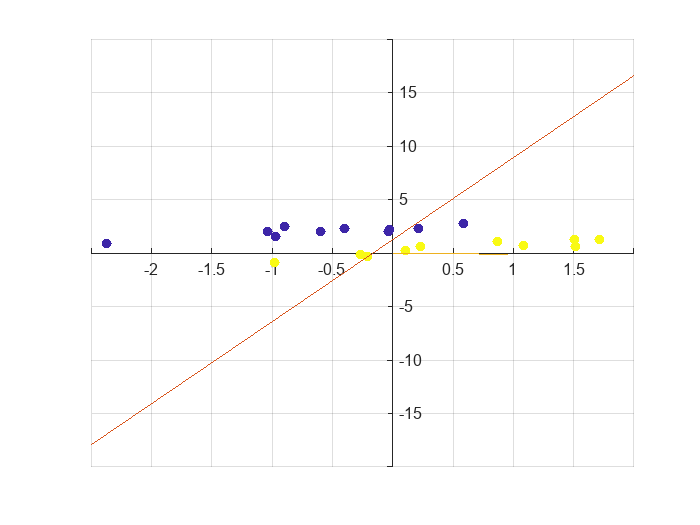

ans = "Iter 3"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.936406 -0.161403], b=-0.231927"

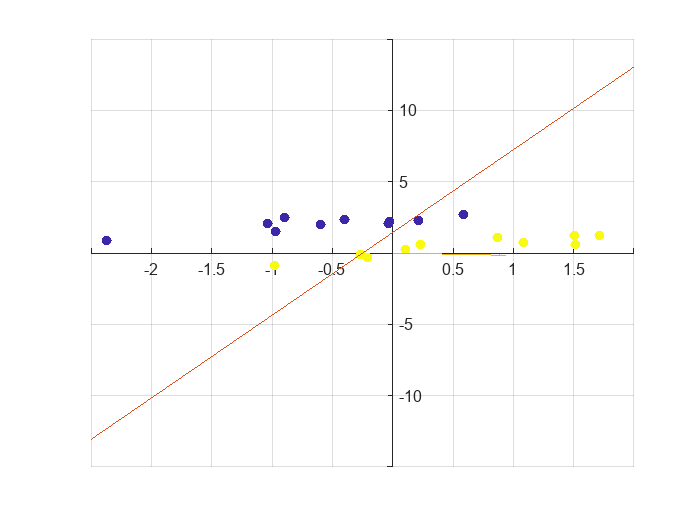

ans = "Iter 4"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.920716 -0.197232], b=-0.231927"

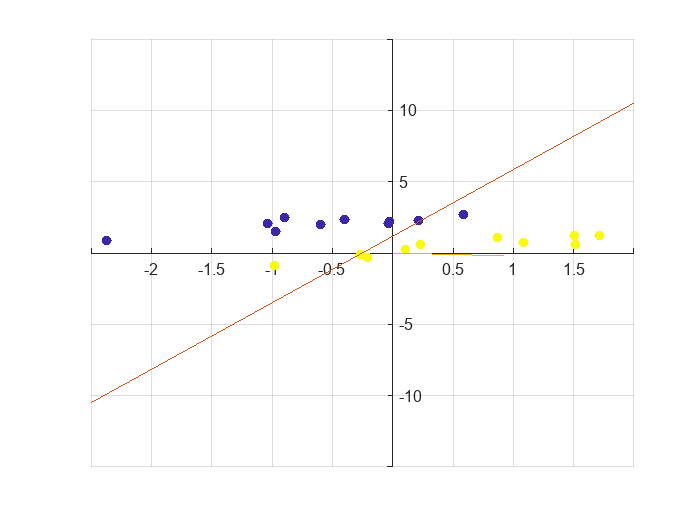

ans = "Iter 5"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.905026 -0.233061], b=-0.231927"

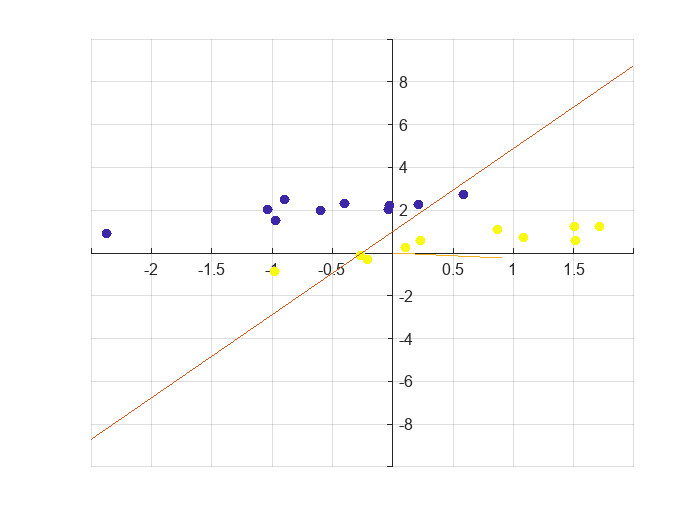

ans = "Iter 6"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.889336 -0.268890], b=-0.231927"

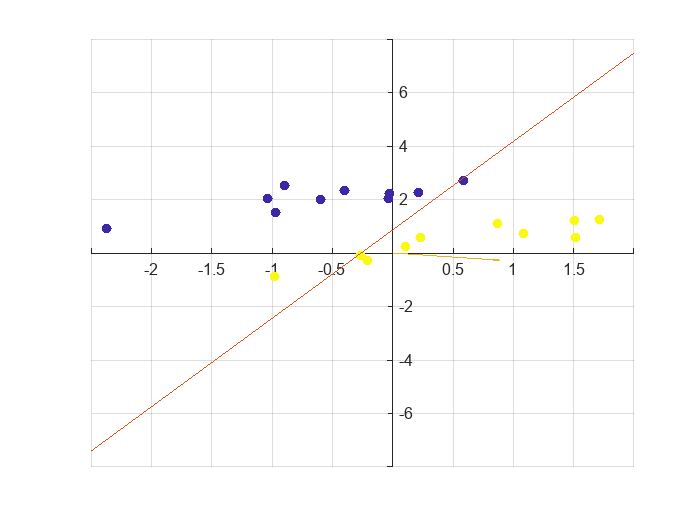

ans = "Iter 7"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.873646 -0.304719], b=-0.231927"

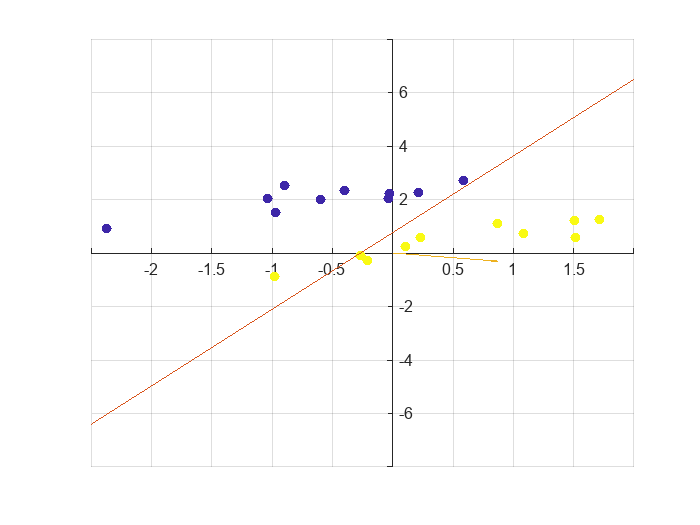

ans = "Iter 8"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.863819 -0.313368], b=-0.309236"

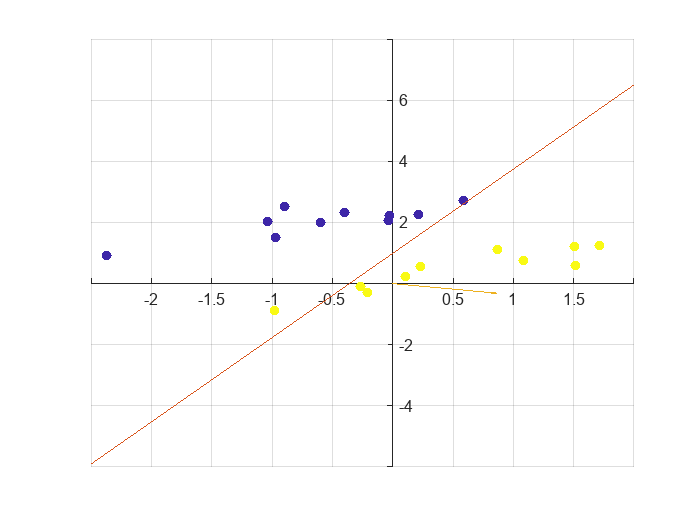

ans = "Iter 9"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.853992 -0.322018], b=-0.386545"

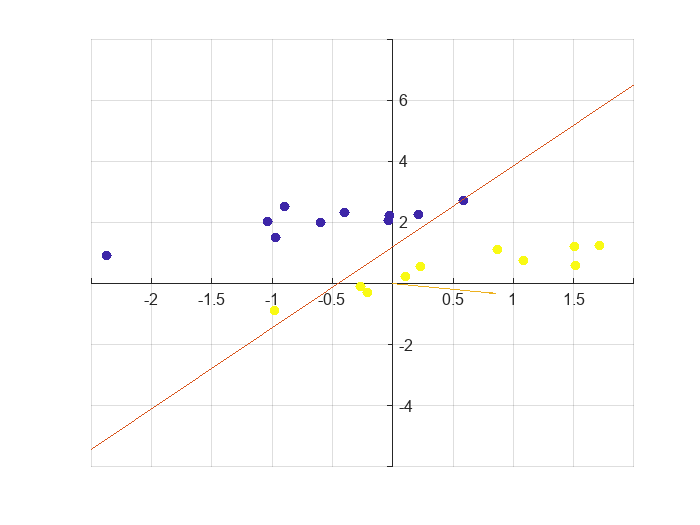

ans = "Iter 10"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.838302 -0.357847], b=-0.386545"

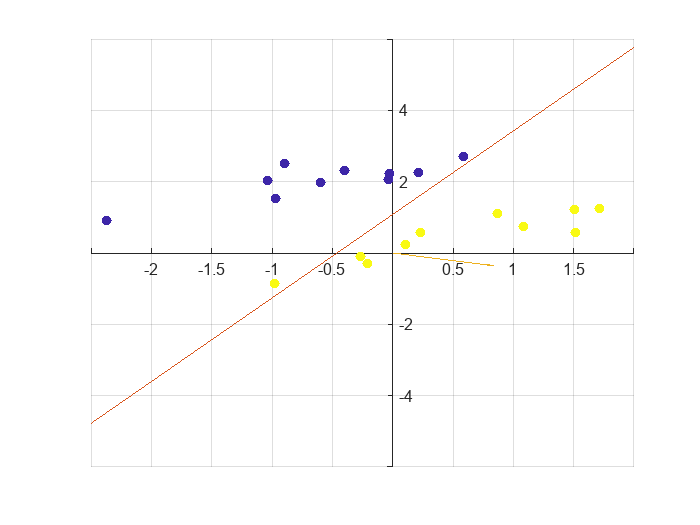

ans = "Iter 11"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.828474 -0.366497], b=-0.463853"

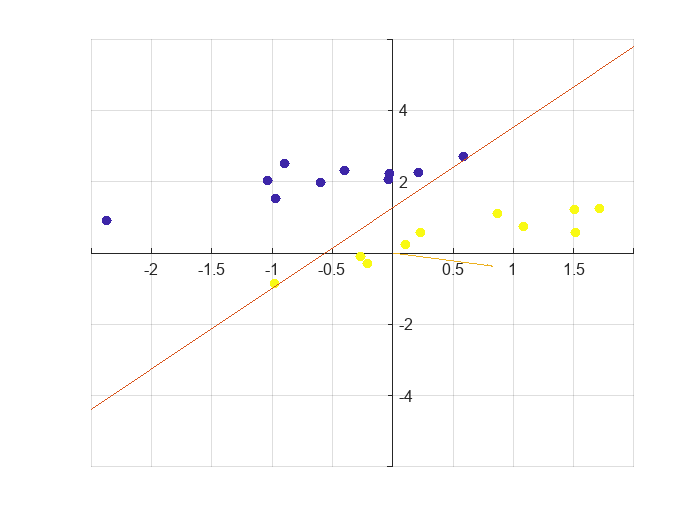

ans = "Iter 12"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.818647 -0.375146], b=-0.541162"

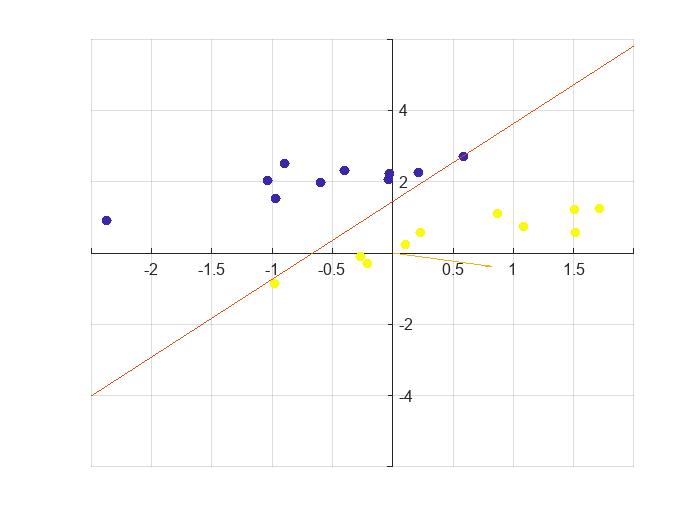

ans = "Iter 13"

ans = "0 errors - error rate : 0.000000"

ans = "w=[0.812785 -0.402326], b=-0.463853"

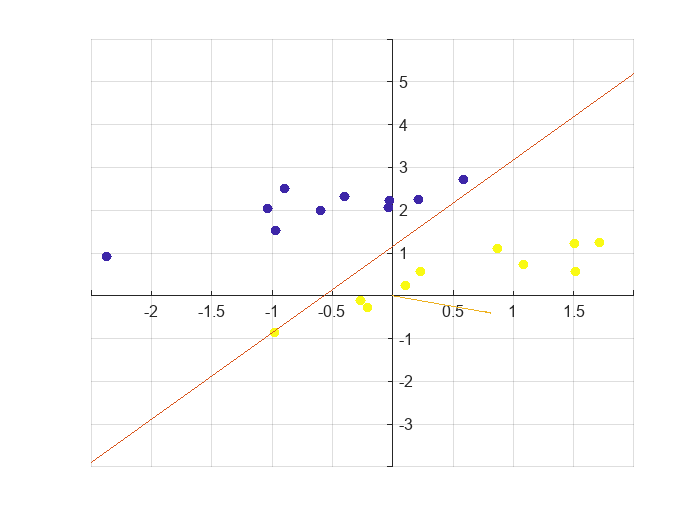

filename = 'animation_case2_1.gif'; 
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

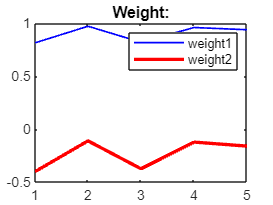

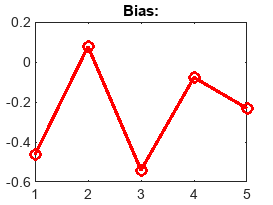

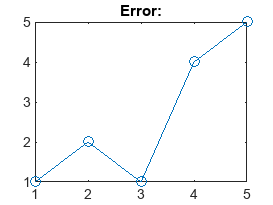

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

% initial classifier 2 : LEARNING RATE=0.01,w=[0 1]
w=[0 1]

w =      0     1


rate=0.01

rate = 0.0100

ans = "Iter 1"

ans = "14 errors - error rate : 70.000000"

ans = "w=[0.056942 0.790356], b=0.386545"

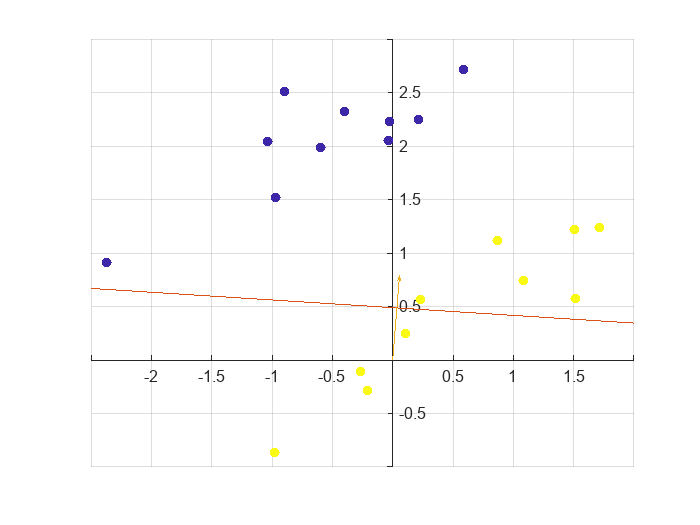

ans = "Iter 2"

ans = "14 errors - error rate : 70.000000"

ans = "w=[0.144180 0.606194], b=0.541162"

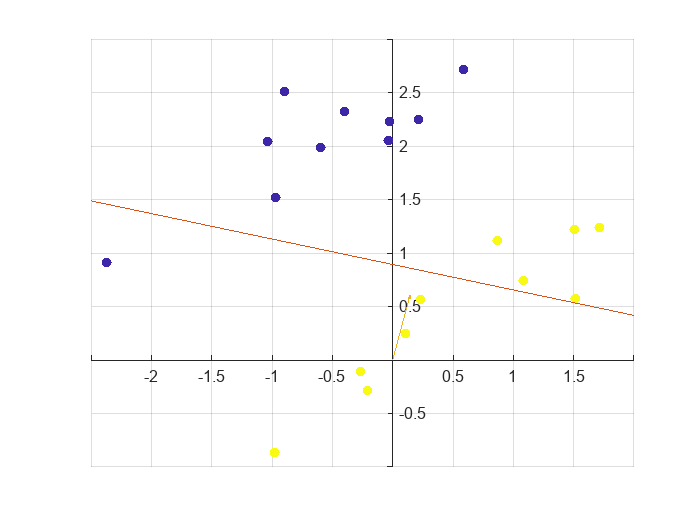

ans = "Iter 3"

ans = "14 errors - error rate : 70.000000"

ans = "w=[0.191319 0.471479], b=0.463853"

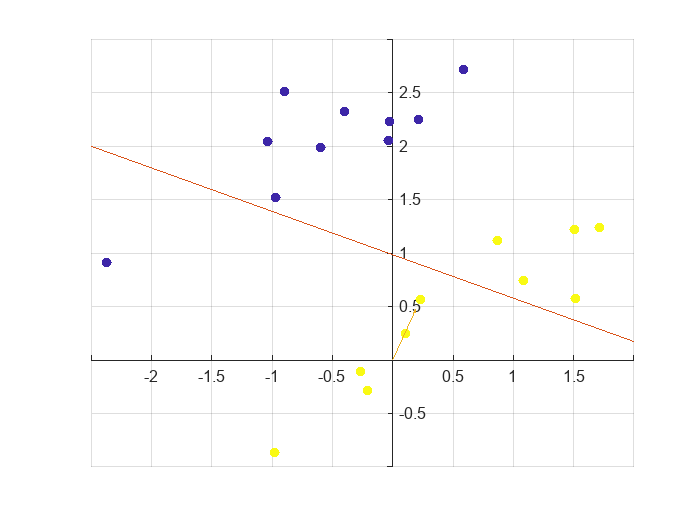

ans = "Iter 4"

ans = "14 errors - error rate : 70.000000"

ans = "w=[0.208986 0.369583], b=0.309236"

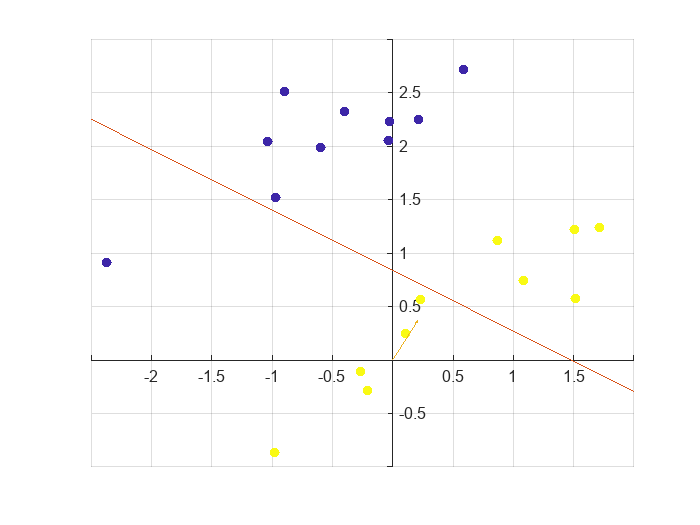

ans = "Iter 5"

ans = "13 errors - error rate : 65.000000"

ans = "w=[0.209492 0.255258], b=0.231927"

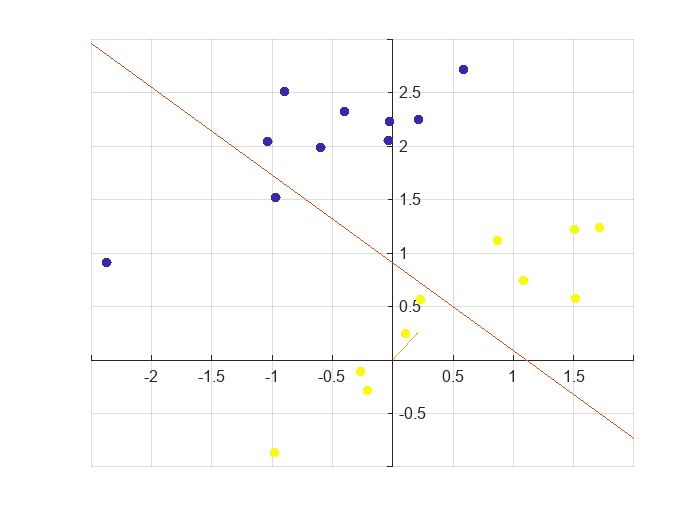

ans = "Iter 6"

ans = "13 errors - error rate : 65.000000"

ans = "w=[0.193000 0.180841], b=0.077309"

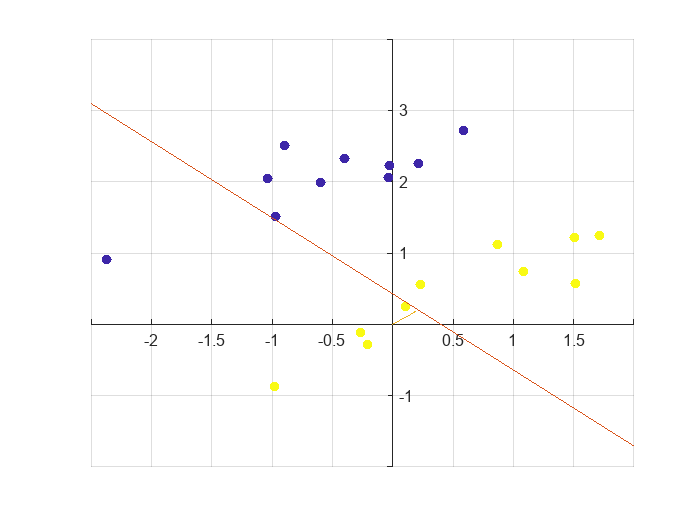

ans = "Iter 7"

ans = "11 errors - error rate : 55.000000"

ans = "w=[0.174187 0.100788], b=-0.000000"

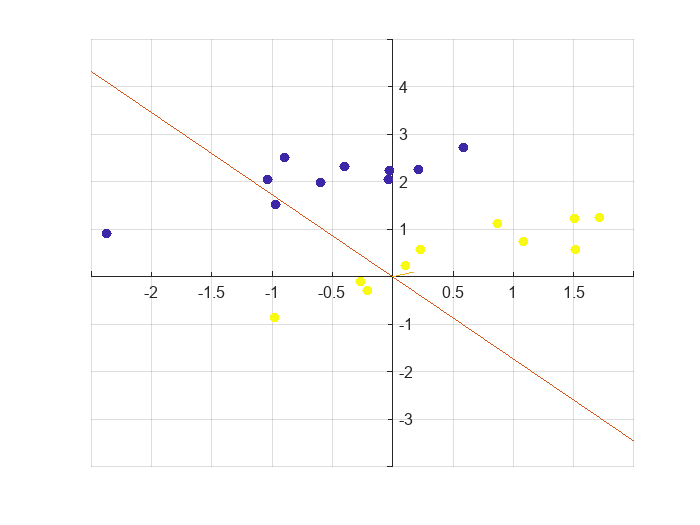

ans = "Iter 8"

ans = "7 errors - error rate : 35.000000"

ans = "w=[0.155375 0.020735], b=-0.077309"

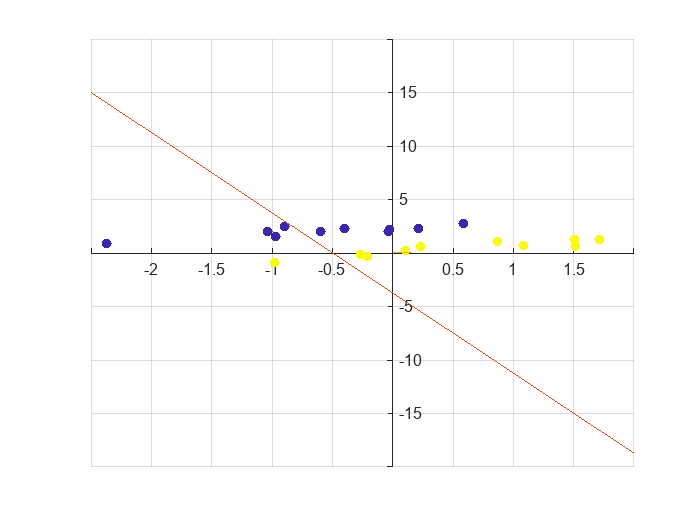

ans = "Iter 9"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.137897 -0.038441], b=-0.077309"

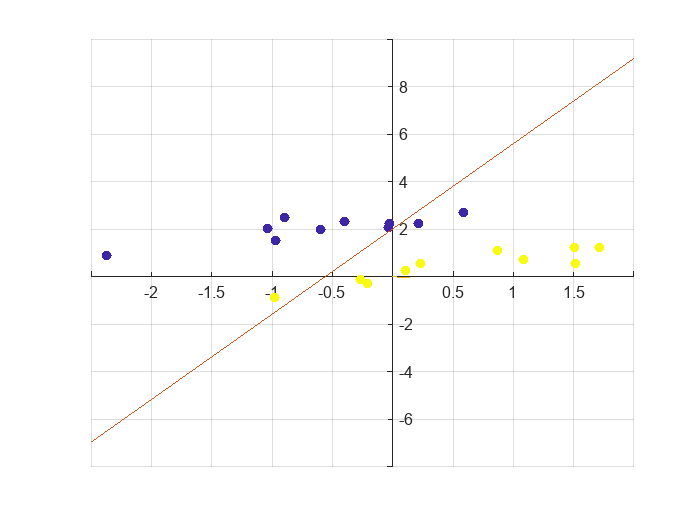

ans = "Iter 10"

ans = "0 errors - error rate : 0.000000"

ans = "w=[0.122207 -0.074270], b=-0.077309"

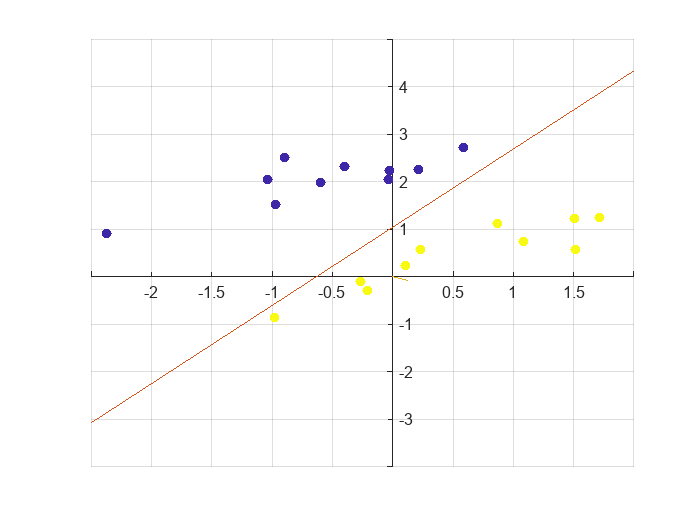

filename = 'animation_case2_2.gif'; % Define the filename for this case
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

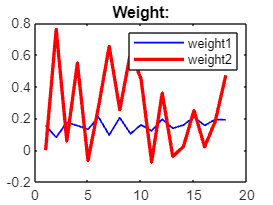

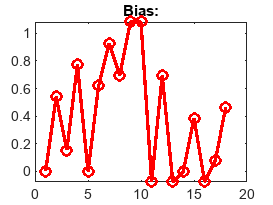

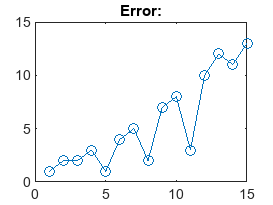

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

% initial classifier 3 : LEARNING RATE=0.01,w=[1 1]
w=[1 1]

w =      1     1


rate=0.01

rate = 0.0100

ans = "Iter 1"

ans = "12 errors - error rate : 60.000000"

ans = "w=[1.018055 0.793655], b=0.386545"

ans = "Iter 2"

ans = "11 errors - error rate : 55.000000"

ans = "w=[1.007053 0.648010], b=0.541162"

ans = "Iter 3"

ans = "10 errors - error rate : 50.000000"

ans = "w=[0.992375 0.527900], b=0.541162"

ans = "Iter 4"

ans = "9 errors - error rate : 45.000000"

ans = "w=[0.973705 0.430992], b=0.463853"

ans = "Iter 5"

ans = "9 errors - error rate : 45.000000"

ans = "w=[0.955035 0.334085], b=0.386545"

ans = "Iter 6"

ans = "8 errors - error rate : 40.000000"

ans = "w=[0.936365 0.237177], b=0.309236"

ans = "Iter 7"

ans = "8 errors - error rate : 40.000000"

ans = "w=[0.917695 0.140270], b=0.231927"

ans = "Iter 8"

ans = "6 errors - error rate : 30.000000"

ans = "w=[0.896480 0.059986], b=0.154618"

ans = "Iter 9"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.874938 0.000218], b=-0.000000"

ans = "Iter 10"

ans = "5 errors - error rate : 25.000000"

ans = "w=[0.852309 -0.062024], b=-0.077309"

ans = "Iter 11"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.831858 -0.101774], b=-0.231927"

ans = "Iter 12"

ans = "3 errors - error rate : 15.000000"

ans = "w=[0.811344 -0.161185], b=-0.231927"

ans = "Iter 13"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.795654 -0.197014], b=-0.231927"

ans = "Iter 14"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.779964 -0.232843], b=-0.231927"

ans = "Iter 15"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.764274 -0.268672], b=-0.231927"

ans = "Iter 16"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.754447 -0.277322], b=-0.309236"

ans = "Iter 17"

ans = "2 errors - error rate : 10.000000"

ans = "w=[0.744619 -0.285971], b=-0.386545"

ans = "Iter 18"

ans = "1 errors - error rate : 5.000000"

ans = "w=[0.728929 -0.321800], b=-0.386545"

ans = "Iter 19"

ans = "0 errors - error rate : 0.000000"

ans = "w=[0.719102 -0.330450], b=-0.463853"

filename = 'animation_case2_3.gif'; % Define the filename for this case
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

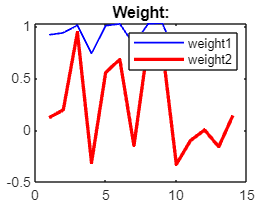

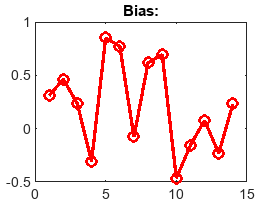

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

% initial classifier 4 : LEARNING RATE=0.01,w=[-1 1]
w=[-1 1]

w =     -1     1


rate=0.01

rate = 0.0100

ans = "Iter 1"

ans = "15 errors - error rate : 75.000000"

ans = "w=[-0.891388 0.833522], b=0.077309"

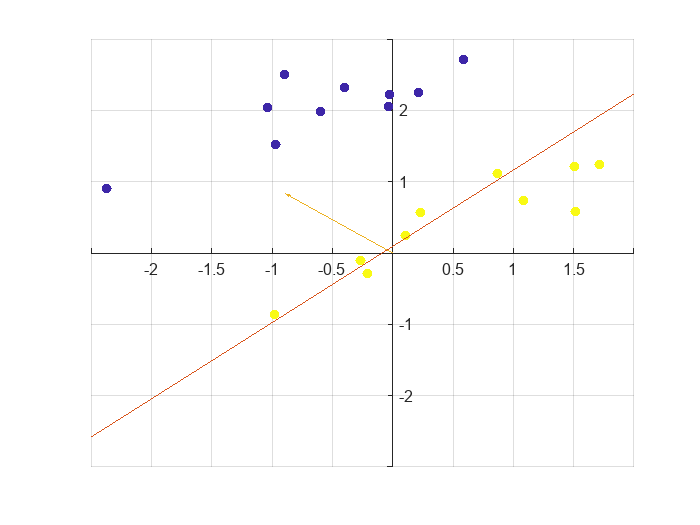

ans = "Iter 2"

ans = "16 errors - error rate : 80.000000"

ans = "w=[-0.780457 0.672682], b=0.077309"

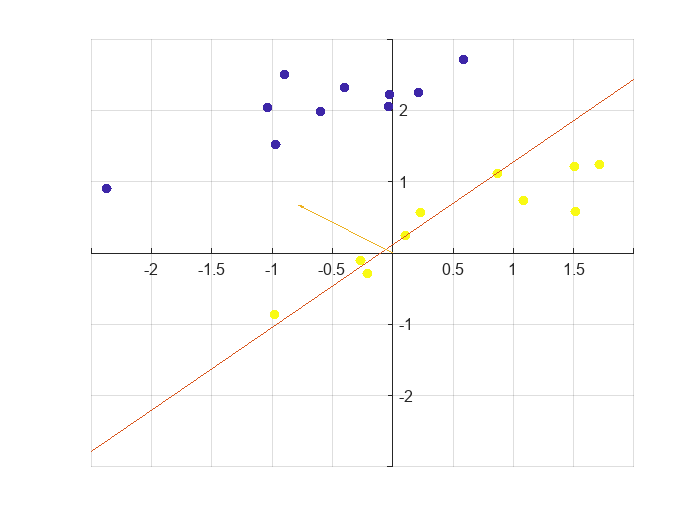

ans = "Iter 3"

ans = "17 errors - error rate : 85.000000"

ans = "w=[-0.669525 0.511842], b=0.077309"

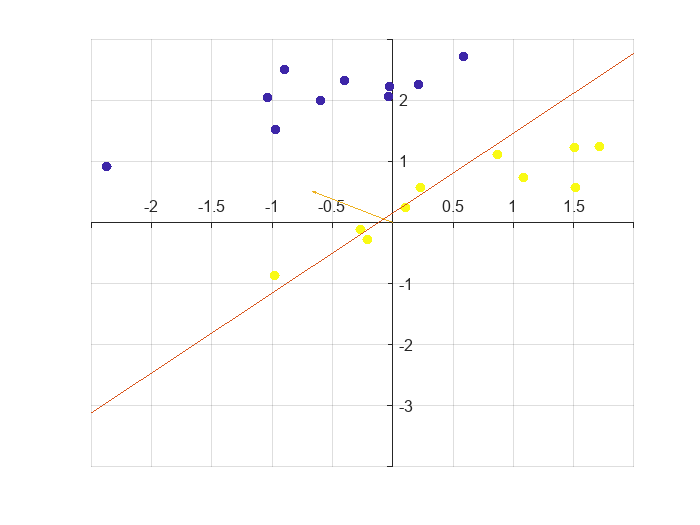

ans = "Iter 4"

ans = "18 errors - error rate : 90.000000"

ans = "w=[-0.558594 0.351001], b=0.077309"

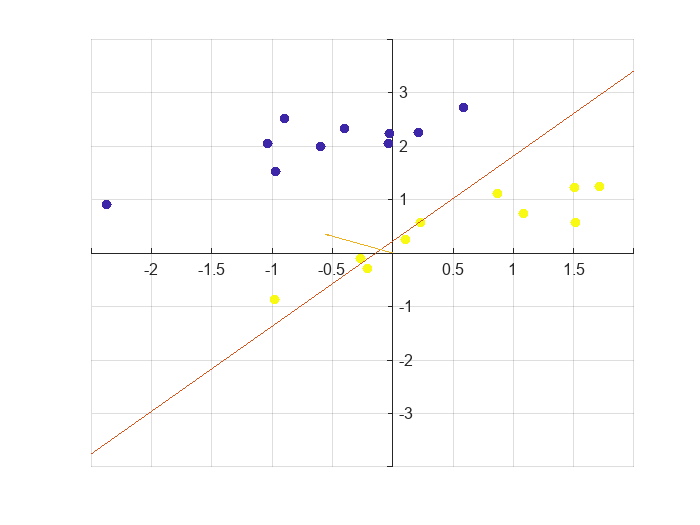

ans = "Iter 5"

ans = "15 errors - error rate : 75.000000"

ans = "w=[-0.445485 0.212652], b=-0.000000"

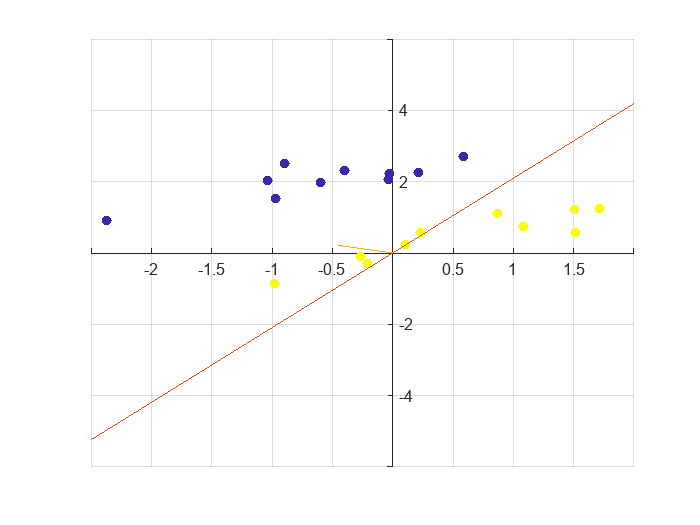

ans = "Iter 6"

ans = "15 errors - error rate : 75.000000"

ans = "w=[-0.326513 0.101482], b=-0.154618"

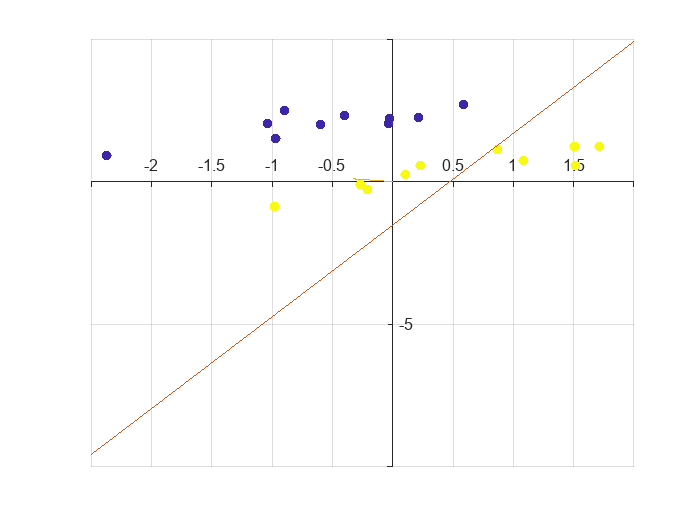

ans = "Iter 7"

ans = "14 errors - error rate : 70.000000"

ans = "w=[-0.230821 0.019613], b=-0.231927"

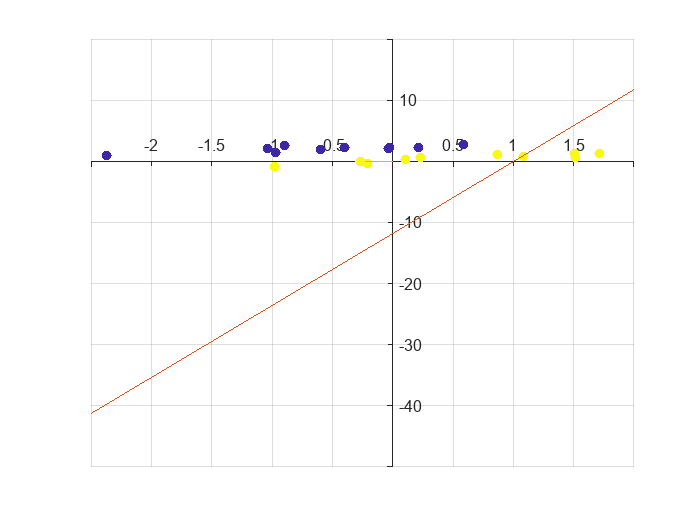

ans = "Iter 8"

ans = "13 errors - error rate : 65.000000"

ans = "w=[-0.140110 -0.037820], b=-0.231927"

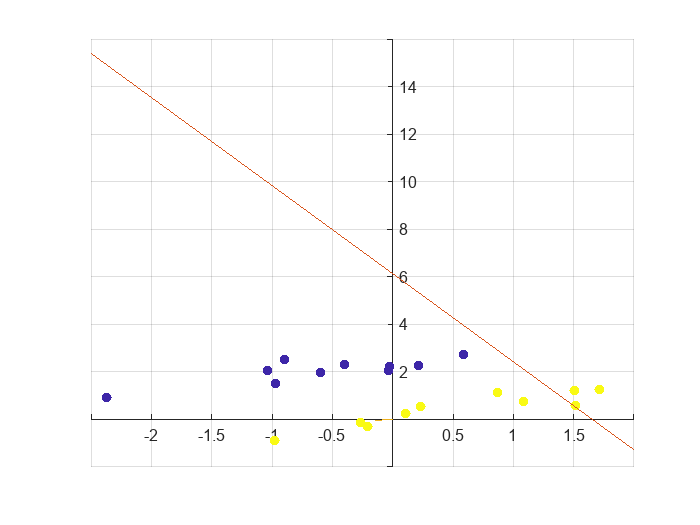

ans = "Iter 9"

ans = "10 errors - error rate : 50.000000"

ans = "w=[-0.058997 -0.052169], b=-0.231927"

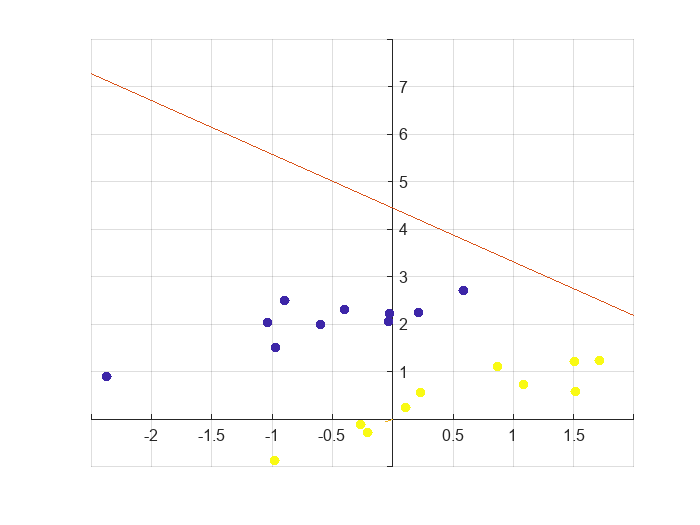

ans = "Iter 10"

ans = "7 errors - error rate : 35.000000"

ans = "w=[-0.017806 -0.069339], b=-0.154618"

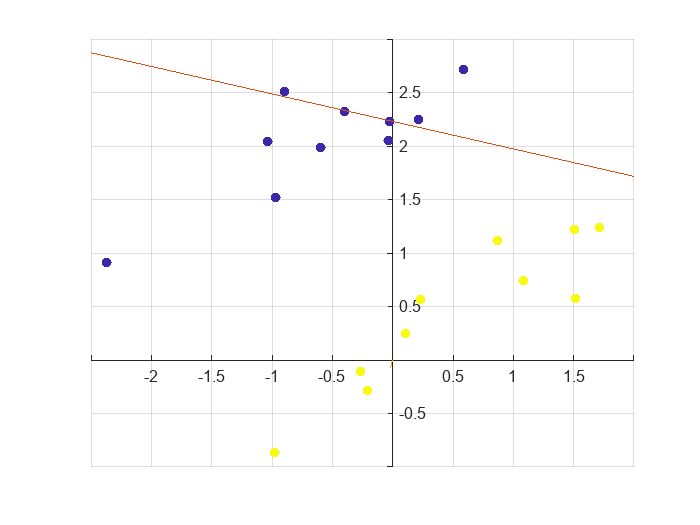

ans = "Iter 11"

ans = "0 errors - error rate : 0.000000"

ans = "w=[0.023384 -0.086509], b=-0.077309"

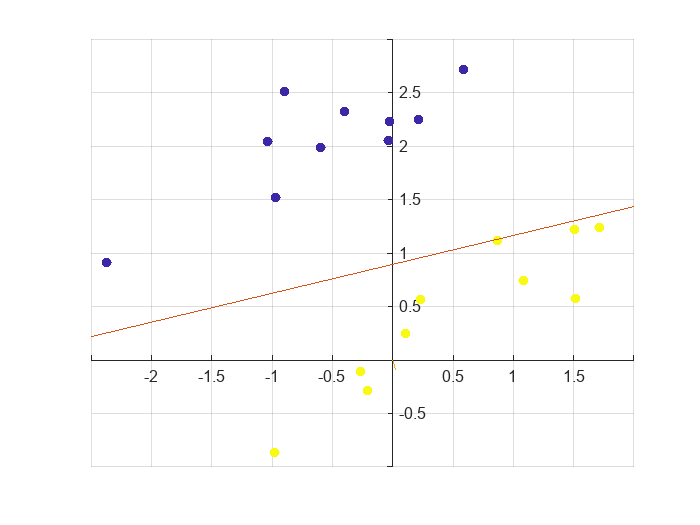

filename = 'animation_case2_4.gif'; % Define the filename for this case
[w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w);

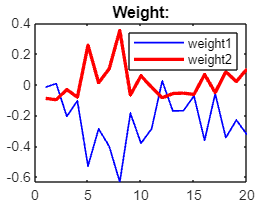

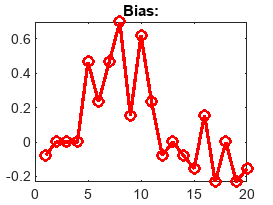

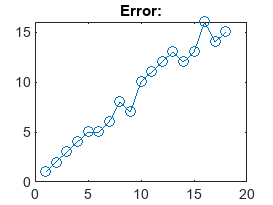

creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename);
percept_plot(w1,b1,erc1);

Functions:

Function 1:

function [w, b, iter, w1, b1, erc1, training_history] = Perceptron_training(x, y, rate, w)
    L = size(x,1);
    w = w;
    b = 0;
    w1 = cell(L,1);
    b1 = cell(L,1);
    erc1 = cell(L,1);
    r = -1;
    
    % Initialize training_history
    training_history = struct;
    training_history.w1 = {};
    training_history.b1 = {};
    
    for i = 1:L
        if norm(x(i,:)) > r
            r = norm(x(i,:));
        end
    end
    
    iter = 0;
    while true
        iter = iter + 1;
        for i = 1:L
           if sign(x(i,:)*w'-b) ~= y(i)
              w = w + rate*y(i)*x(i,:);
              w1{i} = w;
              b = b - rate*y(i)*r*r;
              b1{i} = b;
              
              % Store weights and bias in training_history
              training_history.w1{end+1} = w;
              training_history.b1{end+1} = b;
           end
        end
      
        doBreak = true;
        errcnt = 0;
        for i = 1:L
            if sign(x(i,:)*w'-b) ~= y(i)
                doBreak = false;
                errcnt = errcnt + 1;
                erc1{i} = errcnt;
            end
        end
        errorrate = errcnt/L*100;
        sprintf("Iter %d", iter)
        sprintf("%d errors - error rate : %f",errcnt, errorrate)
        sprintf("w=[%f %f], b=%f", w(1), w(2), b)
        figure(50+iter)
        dec_plot(x,y,w,b)
        if doBreak == true
            break
        end
    end
end

Fucnction 2: 

function percept_plot(W,B,E)
A = cell2mat(W);
x1=A(:,1);
x2=A(:,2);
figure(2);
plot(x1,"LineWidth",1,"Color",'b');
hold on;
plot(x2,"LineWidth",2,"Color",'r');
hold off;
legend('weight1','weight2');
title('Weight:')
figure(3);
B=cell2mat(B);
plot(B,'-o',"LineWidth",2,"Color",'r');
title('Bias:')
figure(4)
C=cell2mat(E);
plot(C,'-o');
title('Error:')
end

Function 3:

function dec_plot(x,y,w,b)
clf
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
grid on
hold on;       
scatter(x(:,1),x(:,2),[],y,'filled')
if (w(2)==0)
    plot([0,0],ylim(1,1),ylim(1,2));
else
    lim = xlim();
    x1=lim(1,1);
    x2=lim(1,2);
    fx1= (-(w(1)/w(2)) *x1  + (b /w(2)));
    fx2= (-(w(1)/w(2)) *x2 + (b /w(2))) ;      
    plot([x1 x2],[fx1 fx2]);
end
hold on
quiver(0, 0, w(1), w(2),1)
grid on        
hold off
hold off
end

Function 4:

function creating_learning_animation(x, y, point_signs, plot_title, axis_vec, training_history, std_id, path, filename)
    rng(std_id);
    
    iterations_amount = length(training_history.w1);
    
    filename = [path, filename]; % Use the filename argument
    
    for i = 1 : iterations_amount
        color = [rand() rand() rand()];
        current_plot_title = [plot_title, ' i = ', num2str(i), ' / ', num2str(iterations_amount)];
        fig = print_iteration(x, y, point_signs, current_plot_title, axis_vec, training_history.w1{i}, training_history.b1{i}, color);
        
        frame = getframe(fig);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        
        % Write to the GIF file
        if i == 1
            imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
        else
            imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
        end
        
        close all
    end
end

Function 5:

function fig = print_iteration(x, y, point_signs, plot_title, axis_vec, w1, b1, color)
    fig = figure;
    hold on
    
    l = length(y);
    
    for i = 1 : l
        if y(i) > 0
            p = plot(x(i, 1), x(i, 2), point_signs(1), 'Color', 'b');
        else 
            p = plot(x(i, 1), x(i, 2), point_signs(2), 'Color', 'r');
        end
        
        if sign(w1 * x(i, :)' - b1) ~= y(i)
            p.Color = [0 0 0];
        end
    end

    if w1(1, 2) == 0
        h = xline(b1 / w1(1, 1));
    else
        h = line(axis_vec(1:2), -w1(1, 1) * axis_vec(1:2) / w1(1, 2) + b1 / w1(1, 2));
    end
        
    h.Color = color;
    
    axis equal;
    axis(axis_vec);
    xlabel('x1');
    ylabel('x2');
    title(plot_title);
    grid on;
end